# Small Network With All Delays

# Test: Correlation terms

## first, setup connctivity map

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
FigurePrePath = [CurrentFolder '/Figures/Demo043021/'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [pwd '/Figures/Demo050721/'];
addpath(DataFolder)
OldDataFolder = [pwd '/Figures/Demo042421-1/'];
addpath(OldDataFolder)
% Make sure the old stuff is the same
load('NtWk_Archit.mat')
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = full(mean(sum(C_EE(E_Ind,:),2))); N_EI = full(mean(sum(C_EI(E_Ind,:),2))*0.75); 
N_IE = full(mean(sum(C_IE(I_Ind,:),2))); N_II = full(mean(sum(C_II(I_Ind,:),2))*0.75); %Plan A:Original
                                                                           %Plan B: Lower #ItoE and #I-to-I

% Now Make a small network s.t. the mean presynaptic neurons are equal to
% above
N_E = floor(2*N_IE); N_I = floor(1/3*N_E);
CS_EE = SmallNetworkGenerat(N_E,N_E,N_EE);
CS_IE = SmallNetworkGenerat(N_E,N_I,N_IE);
CS_EI = SmallNetworkGenerat(N_I,N_E,N_EI);
CS_II = SmallNetworkGenerat(N_I,N_I,N_II);

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.500; rI_amb = 0.500;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80; % 80
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.61;  % was 1.52
                                 % Plan B: Increase S_EI to compensate
                                 % Plan C: 1.57; suboptimal drive
                                 % Plan D: 1.6; optimal drive
                                 % D': NE larger
                                 % Plan E: 1.6; optimal drive
S_II = 0.120; S_IE = S_II*0.153;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 

Now: Delete L6 and amb, and transfer all to LGN.

S_ambU = S_EE; % there is only one Samb...So all align to E
rE_ambU = rE_amb*S_amb/S_ambU; rI_ambU = rI_amb*S_amb/S_ambU;
S_EL6U = S_Elgn; S_IL6U = S_Ilgn;
rE_L6U = rE_L6*S_EL6/S_EL6U;     rI_L6U = rI_L6*S_IL6/S_IL6U; %250hz for now

## Now, with drive

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

- Kicks are all normalized to LGN sizes

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lgnE_Drive = [60,50,42,50]*4/1e3;
lgnI_Drive = min(lgnE_Drive);
lambda_E_drive = lgnE_Drive(1);
lambda_I_drive = lgnI_Drive;

L6E_Drive = [50 35 20 35]*50/1e3;
L6I_Drive = min(L6E_Drive);
rE_L6_DriveU = L6E_Drive(1)*S_EL6/S_EL6U;
rI_L6_DriveU = 3*rE_L6_DriveU*S_IL6/S_IL6U;


% Making Poisson here/Reading
T = 50000; dt = 0.1;
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_ambU,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_ambU,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_DriveU*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_DriveU*(1-L6CurInp),T*TimeFrac,dt);

%   [A,~,Times] = find(eventsN);

Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

% E-to-E delay time
T_EEDly = .9; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .5; N_IEDly = floor(T_IEDly/dt);
T_EIDly = 0.5; N_EIDly = floor(T_EIDly/dt);
% % The initial states
% InSs = load('Initials_L6.mat');
% RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
% GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
% RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
% GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
% EEDlyRcd = sparse(N_E,N_EEDly);

% The initial states, for more simulation 
%load(['DriveWkSp_TestDly_EE0.8_IE0.8_17.mat'],'EndState');
% load('DriveWk_SNW_Sp_TestDly_EE0.9_IE0.5_NMDA80_40-45_C.mat','EndState');
% RefTimeE = EndState{1}; VE = EndState{2}; SpE = EndState{3}; GE_ampa_R = EndState{4}; GE_nmda_R = EndState{5}; GE_gaba_R = EndState{6};
%                                                              GE_ampa_D = EndState{7}; GE_nmda_D = EndState{8}; GE_gaba_D = EndState{9};
% RefTimeI = EndState{10}; VI = EndState{11}; SpI = EndState{12}; GI_ampa_R = EndState{13}; GI_nmda_R = EndState{14}; GI_gaba_R = EndState{15};
%                                                                 GI_ampa_D = EndState{16}; GI_nmda_D = EndState{17}; GI_gaba_D = EndState{18};
% if N_EEDly>=size(EndState{19},2)
% EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
% else
%     EEDlyRcd = EndState{19}(:,1:N_EEDly);
% end
% if N_IEDly>=size(EndState{20},2)
% IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
% else
%     IEDlyRcd = EndState{20}(:,1:N_IEDly);
% end
% if N_EIDly>=size(EndState{21},2)
% EIDlyRcd = [EndState{21},zeros(N_E,N_EIDly-size(EndState{20},2))]; 
% else
%     EIDlyRcd = EndState{21}(:,1:N_EIDly);
% end
%EIDlyRcd = repmat(CS_EI*SpI,1,N_EIDly);
% Create sliding windows
sampleT = 200;
Sliding = 200;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

But to accelerate, we exclude L6 Current Input at first...

TPar = 10;
TSimOne = floor(T/TPar/1e3);

Load data from cretain regime

%DataFolder = [pwd '/Figures/Demo042221/'];
TPar = 10;
% read data, and get spike and mV
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
for TSec = 1:TPar
    text = sprintf('DriveWk_SNW_Sp_TestDly_EE%.1f_IE%.1f_NMDA%d_%d-%d_Ep.mat',T_EEDly,T_IEDly, tau_nmda_D,...
                                                     TSimOne*(TSec-1),TSimOne*TSec);
    load([DataFolder text],'NWTrace');
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
end
WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
WinSize = StatWin(2) - StatWin(1);

SNWData.VE = nanmean(mVE);
SNWData.VI = nanmean(mVI);
SNWData.SpE = histcounts(SpE(:,2),StatWin);
SNWData.SpI = histcounts(SpI(:,2),StatWin);
clear mVE mVI SpE SpI

Smth = 1;
SNWData.VE = conv(SNWData.VE,1/Smth*ones(1,Smth)); SNWData.VE = SNWData.VE(Smth:end-Smth+1);
SNWData.VI = conv(SNWData.VI,1/Smth*ones(1,Smth)); SNWData.VI = SNWData.VI(Smth:end-Smth+1);
SNWData.SpE = conv(SNWData.SpE,1/Smth*ones(1,Smth)); SNWData.SpE = SNWData.SpE(Smth:end-Smth+1);
SNWData.SpI = conv(SNWData.SpI,1/Smth*ones(1,Smth)); SNWData.SpI = SNWData.SpI(Smth:end-Smth+1);

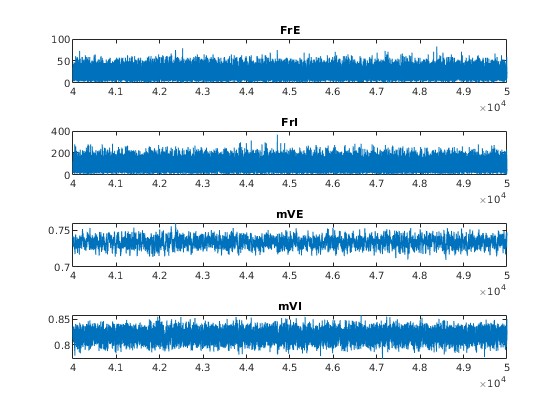


figure("Name",'Traj on Time')
subplot 411
plot(StatWin(1:end-Smth),SNWData.SpE/N_E/WinSize*1e3)
title('FrE');xlim([4e4 5e4])
subplot 412
plot(StatWin(1:end-Smth),SNWData.SpI/N_I/WinSize*1e3)
title('FrI');xlim([4e4 5e4])
subplot 413
plot(StatWin(1:end-Smth),SNWData.VE)
title('mVE');xlim([4e4 5e4])
subplot 414
plot(StatWin(1:end-Smth),SNWData.VI)
title('mVI');xlim([4e4 5e4])

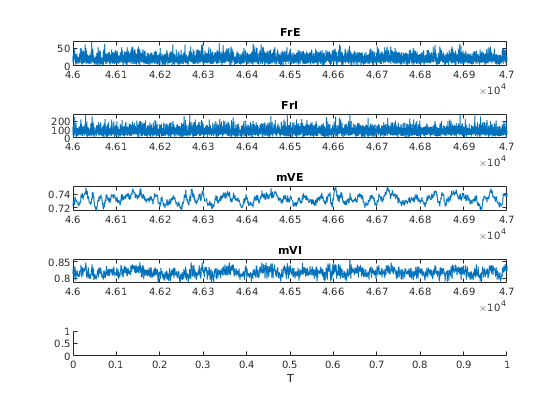


figure("Name",'Raster')
Xrange = [46000 47000];
subplot 511
plot(StatWin(1:end-Smth),SNWData.SpE/N_E/WinSize*1e3)
title('FrE');xlim(Xrange)
subplot 512
plot(StatWin(1:end-Smth),SNWData.SpI/N_I/WinSize*1e3)
title('FrI');xlim(Xrange)
subplot 513
plot(StatWin(1:end-Smth),SNWData.VE)
title('mVE');xlim(Xrange)
subplot 514
plot(StatWin(1:end-Smth),SNWData.VI)
title('mVI');xlim(Xrange)
subplot 515
hold on
%ENeu = floor(N_E/2):N_E; INeu = 1:floor(N_I/2);
% scatter(SpE(:,2), SpE(:,1),0.1 ,'r.')
% scatter(SpI(:,2), SpI(:,1)+max(SpE(:,1)) , 0.1,'b.')
% xlim(Xrange); ylim([floor(N_E*2/3),N_E+floor(N_I/3)])
xlabel('T')

## Correlation Maps

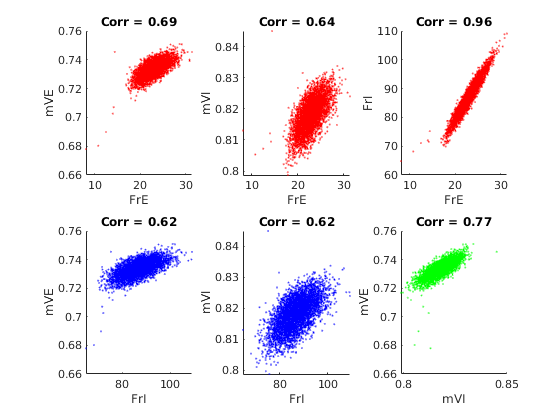

Res = 10; %change bin resolution to 4ms
NewBinSz = floor(Res/WinSize);
Len = length(StatWin)-Smth;
SNWDataRes.SpE = mean(reshape(SNWData.SpE,NewBinSz,floor(Len/NewBinSz)),1);
SNWDataRes.SpI = mean(reshape(SNWData.SpI,NewBinSz,floor(Len/NewBinSz)),1);
SNWDataRes.VE = mean(reshape(SNWData.VE,NewBinSz,floor(Len/NewBinSz)),1);
SNWDataRes.VI = mean(reshape(SNWData.VI,NewBinSz,floor(Len/NewBinSz)),1);
hCorr_Bin = CorrCoefFig(SNWDataRes.SpE/N_E/WinSize*1e3, SNWDataRes.SpI/N_I/WinSize*1e3,...
                    SNWDataRes.VE,                  SNWDataRes.VI);

## Then we check how things goes within each large Bin

By removing the sliding mean

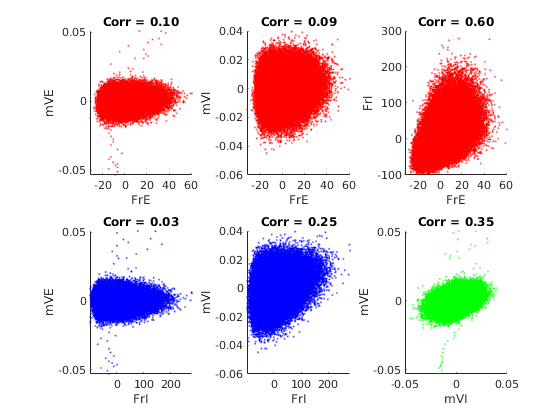

SNWDataFilt.SpE = SNWData.SpE - reshape(repmat(SNWDataRes.SpE,NewBinSz,1),1,length(SNWData.SpE));
SNWDataFilt.SpI = SNWData.SpI - reshape(repmat(SNWDataRes.SpI,NewBinSz,1),1,length(SNWData.SpI));
SNWDataFilt.VE = SNWData.VE - reshape(repmat(SNWDataRes.VE,NewBinSz,1),1,length(SNWData.VE));
SNWDataFilt.VI = SNWData.VI - reshape(repmat(SNWDataRes.VI,NewBinSz,1),1,length(SNWData.VI));
hCorr_Filt = CorrCoefFig(SNWDataFilt.SpE/N_E/WinSize*1e3, SNWDataFilt.SpI/N_I/WinSize*1e3,...
                         SNWDataFilt.VE,                  SNWDataFilt.VI);

## Consider direct sin(t) representations

f_pre = [mean(SNWDataRes.SpE/N_E/WinSize*1e3);
         mean(SNWDataRes.SpI/N_I/WinSize*1e3)];
mVE = mean(SNWDataRes.VE); mVI = mean(SNWDataRes.VI);

ref_fac = 1-f_pre*tau_ref/1000;
% Matrix of firing rates
MatEI = [N_EE*S_EE*(Ve-mVE)*(1-p_EEFail), N_EI*S_EI*(Vi-mVE);
         N_IE*S_IE*(Ve-mVI),              N_II*S_II*(Vi-mVI)];

% External Drive and leaky current. Note that simulaton is by ms, so need *1000
VecInput = [(Ve-mVE) * (lambda_E_drive*S_Elgn + rE_ambU*S_ambU + rE_L6_DriveU*S_EL6U);
            (Ve-mVI) * (lambda_I_drive*S_Ilgn + rI_ambU*S_ambU + rI_L6_DriveU*S_IL6U)]*1000;
Leak = -[gL_E*mVE;
         gL_I*mVI]*1000; % leak has opposite signs of mean Vs

f_MF = ref_fac.*(MatEI*f_pre + (VecInput + Leak))

f_MF = 2×1 single column vector
   28.5020
  100.8134


Correlation terms

% SNWfft.FrE = fft(SNWDataRes.SpE/N_E/WinSize*1e3);
% SNWfft.FrI = fft(SNWDataRes.SpI/N_I/WinSize*1e3)
% SNWfft.mVE = fft(SNWDataRes.VE);
% SNWfft.mVI = fft(SNWDataRes.VI);
CorMat = corrcoef([SNWDataRes.SpE'/N_E/WinSize*1e3, SNWDataRes.SpI'/N_I/WinSize*1e3, SNWDataRes.VE', SNWDataRes.VI']);

% aE = sqrt(mean((SNWDataRes.SpE/N_E/WinSize*1e3 - f_pre(1)).^2)); aI = sqrt(mean((SNWDataRes.SpI/N_I/WinSize*1e3 - f_pre(2)).^2));
% bE = sqrt(mean((SNWDataRes.VE - mVE).^2));   bI = sqrt(mean((SNWDataRes.VI - mVI).^2)); 
xx = 0:0.02:1;
Cor_EnI = zeros(length(xx),length(xx),length(xx),length(xx),2);
Cor_EnICor = zeros(length(xx),length(xx),length(xx),length(xx),2);
AveErr = zeros(length(xx),length(xx),length(xx),length(xx));
AveErrCor = zeros(length(xx),length(xx),length(xx),length(xx));
aEAll = f_pre(1)/2*xx; aIAll = f_pre(2)/2*xx;
bEAll = 0.1*xx;   bIAll = 0.1*xx;
for aEInd = 1:length(xx)
    aE = aEAll(aEInd);
    for aIInd = 1:length(xx)
        aI = aIAll(aIInd);
        for bEInd = 1:length(xx)
            bE = bEAll(bEInd);
            for bIInd = 1:length(xx)
                bI = bIAll(bIInd);
                
                COR_E = -tau_ref/1000*aE * (- gL_E*bE*1000 ...
                    + N_EE*S_EE*(Ve-mVE)*(1-p_EEFail)*aE ...
                    - ((lambda_E_drive*S_Elgn + rE_ambU*S_ambU + rE_L6_DriveU*S_EL6U)*1000 + N_EE*S_EE*(1-p_EEFail)*f_pre(1))*bE ...
                    + N_EI*S_EI*(Vi-mVE)*aI - N_EI*S_EI*f_pre(2)*bE) ...
                    +(1-tau_ref/1000*f_pre(1)) * (-N_EE*S_EE*(1-p_EEFail)*aE*bE - N_EI*S_EI*aI*bE);
                
                COR_I = -tau_ref/1000*aI * (- gL_I*bI*1000 ...
                    + N_IE*S_IE*(Ve-mVI)*aE ...
                    - ((lambda_I_drive*S_Ilgn + rI_ambU*S_ambU + rI_L6_DriveU*S_IL6U)*1000 + N_IE*S_IE*f_pre(1))*bI ...
                    + N_II*S_II*(Vi-mVI)*aI - N_II*S_II*f_pre(2)*bI) ...
                    +(1-tau_ref/1000*f_pre(2)) * (-N_IE*S_IE*aE*bI - N_II*S_II*aI*bI);
                Cor_EnI(aEInd,aIInd,bEInd,bIInd,:) = [COR_E;COR_I];
                AveErr(aEInd,aIInd,bEInd,bIInd) = sqrt((sum((f_MF + [COR_E;COR_I]/2)./f_pre - [1;1])).^2);
                
                % What if we add the correlation coefficients?
                COR_ECor = -tau_ref/1000*aE * (- gL_E*bE*1000 * CorMat(1,3)...
                    + N_EE*S_EE*(Ve-mVE)*(1-p_EEFail)*aE ...
                    - ((lambda_E_drive*S_Elgn + rE_ambU*S_ambU + rE_L6_DriveU*S_EL6U)*1000 + N_EE*S_EE*(1-p_EEFail)*f_pre(1))*bE * CorMat(1,3)...
                    + N_EI*S_EI*(Vi-mVE)*aI * CorMat(1,2)- N_EI*S_EI*f_pre(2)*bE * CorMat(1,3)) ...
                    +(1-tau_ref/1000*f_pre(1)) * (-N_EE*S_EE*(1-p_EEFail)*aE*bE * CorMat(1,3) - N_EI*S_EI*aI*bE * CorMat(2,3));
                
                COR_ICor = -tau_ref/1000*aI * (- gL_I*bI*1000 * CorMat(2,4)...
                    + N_IE*S_IE*(Ve-mVI)*aE * CorMat(2,1)...
                    - ((lambda_I_drive*S_Ilgn + rI_ambU*S_ambU + rI_L6_DriveU*S_IL6U)*1000 + N_IE*S_IE*f_pre(1))*bI * CorMat(2,4)...
                    + N_II*S_II*(Vi-mVI)*aI - N_II*S_II*f_pre(2)*bI * CorMat(2,4)) ...
                    +(1-tau_ref/1000*f_pre(2)) * (-N_IE*S_IE*aE*bI * CorMat(1,4)- N_II*S_II*aI*bI * CorMat(2,4));
                Cor_EnICor(aEInd,aIInd,bEInd,bIInd,:) = [COR_ECor;COR_ICor];
                AveErrCor(aEInd,aIInd,bEInd,bIInd) = sqrt((sum((f_MF + [COR_ECor;COR_ICor]/2)./f_pre - [1;1])).^2);
            end
        end
    end
end

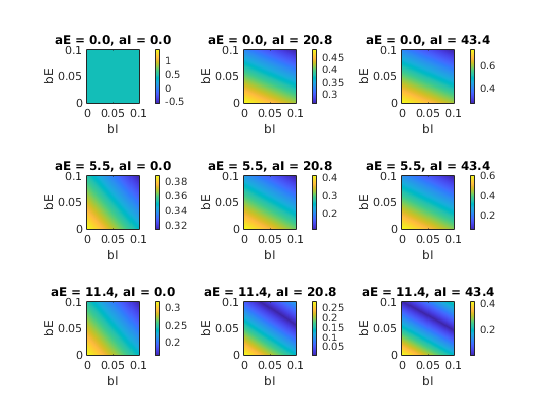


CorCoefInd = [1,floor(length(xx)/2),length(xx)];
figure('Name','Fix_aEaI')
for aa = 1:length(CorCoefInd)
    for bb = 1:length(CorCoefInd)
            subplot(length(CorCoefInd),length(CorCoefInd),(aa-1)*length(CorCoefInd)+bb)
            CurrentPlain = squeeze(AveErr(CorCoefInd(aa),CorCoefInd(bb),:,:));
            imagesc(bIAll,bEAll,CurrentPlain)
            colorbar
            title(sprintf('aE = %.1f, aI = %.1f',aEAll(CorCoefInd(aa)),aIAll(CorCoefInd(bb))))
            xlabel('bI'); ylabel('bE')
            set(gca,'YDir','Normal')
            axis square
    end
end

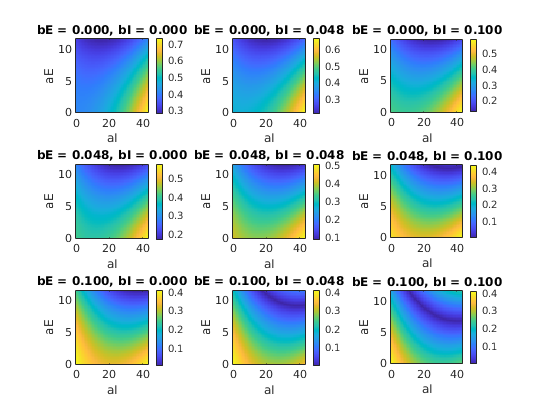


figure('Name','Fix_bEbI')
for aa = 1:length(CorCoefInd)
    for bb = 1:length(CorCoefInd)
            subplot(length(CorCoefInd),length(CorCoefInd),(aa-1)*length(CorCoefInd)+bb)
            CurrentPlain = squeeze(AveErr(:,:,CorCoefInd(aa),CorCoefInd(bb)));
            imagesc(aIAll,aEAll,CurrentPlain)
            colorbar
            title(sprintf('bE = %.3f, bI = %.3f',bEAll(CorCoefInd(aa)),bIAll(CorCoefInd(bb))))
            xlabel('aI'); ylabel('aE')
            set(gca,'YDir','Normal')
            axis square
    end
end

## See if plain integration makes sense

fEt = SNWDataRes.SpE/N_E/WinSize*1e3; fIt = SNWDataRes.SpI/N_I/WinSize*1e3;
VEt = SNWDataRes.VE;                  VIt = SNWDataRes.VI;

tNMDA = 0:Res:4*tau_nmda_D;
NMDAKer = (exp(-tNMDA/tau_nmda_D) - exp(-tNMDA/tau_nmda_R))/sum(exp(-tNMDA/tau_nmda_D) - exp(-tNMDA/tau_nmda_R));
Lent = length(fEt);
gEEtNMDA = conv(rhoE_nmda*N_EE*S_EE*(1-p_EEFail)*fEt, NMDAKer);
gIEtNMDA = conv(rhoI_nmda*N_IE*S_IE*fEt, NMDAKer);

gEEt = (lambda_E_drive*S_Elgn + rE_ambU*S_ambU + rE_L6_DriveU*S_EL6U)*1000 + rhoE_ampa*N_EE*S_EE*(1-p_EEFail)*fEt + gEEtNMDA(1:Lent);
gEIt = N_EI*S_EI*fIt;
gIEt = (lambda_I_drive*S_Ilgn + rI_ambU*S_ambU + rI_L6_DriveU*S_IL6U)*1000 + rhoI_ampa*N_IE*S_IE*fEt + gIEtNMDA(1:Lent);
gIIt = N_II*S_II*fIt;

fEInt = 1/T * Res * sum((1-tau_ref/1000*fEt).*(-gL_E*VEt + gEEt.*(Ve-VEt) + gEIt.*(Vi-VEt)));
fIInt = 1/T * Res * sum((1-tau_ref/1000*fIt).*(-gL_I*VIt + gIEt.*(Ve-VIt) + gIIt.*(Vi-VIt)));